
% DATASET LOADING

%javaaddpath('C:\Program Files\MATLAB\R2024a\java\jar/KaraokeMidiJava.jar'); %this is for the readmidi_java function
% Specify the folder containing MIDI files
folderPath = "D:\TANVI_COLLEGE_FILES\ESMT_PROJECT_SEM5\maestro-v3.0.0-midi\maestro-v3.0.0\2006";

% process multiple midi files, loop thru each file in the folder 
midiFiles = dir(fullfile(folderPath, '*.midi'));
midiData = {};
for i = 1:length(midiFiles)
    midiFilePath = fullfile(folderPath, midiFiles(i).name);
    try
        midiMatrix = readmidi(midiFilePath);
        midiData{i} = midiMatrix;
    catch ME
        disp(['Error Reading MIDI file: ', midiFiles(i).name]);
        disp(ME.message);
    end
end

% midiMatrix = readmidi(folderPath + "\MIDI-Unprocessed_01_R1_2006_01-09_ORIG_MID--AUDIO_01_R1_2006_01_Track01_wav.midi");

% midiMatrix = readmidi(folderPath);

pitchColumn = 4;    % MIDI pitch values
timeColumn = 1;     % Time in seconds
durationColumn = 7; % Duration in seconds

%%
% CHECKING RANGES OF PITCH, TIME AND DURATION TO SEE IF THEY ARE VALID
% Check pitch values
pitch_values = midiMatrix(:, pitchColumn);
disp('Pitch value range:');

Pitch value range:


disp([min(pitch_values), max(pitch_values)]);

    21   103




% Check time values
time_values = midiMatrix(:, timeColumn);
disp('Time value range:');

Time value range:


disp([min(time_values), max(time_values)]);

   1.0e+03 *

    0.0029    2.7919




% Check duration values
duration_values = midiMatrix(:, durationColumn);
disp('Duration value range:');

Duration value range:


disp([min(midiMatrix(:, durationColumn)), max(midiMatrix(:, durationColumn))]);

    0.0013    5.2773




% Check for negative or unusual values
disp('Negative pitch values:');

Negative pitch values:


disp(pitch_values(pitch_values < 0));

disp('Negative time values:');

Negative time values:


disp(time_values(time_values < 0));
    
disp('Zero or negative duration values:');

Zero or negative duration values:


disp(duration_values(duration_values <= 0));

%%
% CREATE MATRIX OF TIME, PITCH, DURATION

notes = [time_values, pitch_values, duration_values];

disp('Extracted Notes (Time, Pitch, Duration):');

Extracted Notes (Time, Pitch, Duration):


disp(notes(1:10, :));  % Display the first 10 notes

    2.9479   55.0000    0.1432
    2.9557   31.0000    0.1914
    2.9714   43.0000    0.1328
    7.4974   55.0000    0.1172
    7.5078   43.0000    0.1393
    7.5365   31.0000    0.1667
   12.4323   43.0000    4.6133
   12.4427   55.0000    4.2513
   12.5599   31.0000    0.1901
   14.4896   53.0000    1.6732




%%
% ONE HOT ENCODING FOR PITCH COLUMN

% One-hot encoding for pitch values
numPitches = 128;  % MIDI range from 0 to 127
oneHotPitches = zeros(size(pitch_values, 1), numPitches);

for i = 1:size(pitch_values, 1)
    if pitch_values(i) >= 0 && pitch_values(i) <= 127
        oneHotPitches(i, pitch_values(i) + 1) = 1;  % +1 for 1-based indexing in MATLAB
    end
end

% Combine the time and duration with the one-hot encoded pitches
encodedNotes = [time_values, oneHotPitches, duration_values];

% Display the dimensions of the encoded notes
disp('Dimensions of Encoded Notes:');

Dimensions of Encoded Notes:


disp(size(encodedNotes));

       16793         130




%%
% NORMALIZATION OF TIME AND DURATION TO GET THEIR VALUES B/W 0 AND 1

% Normalize the time and duration values to the range [0, 1]
time_min = min(encodedNotes(:, 1));
time_max = max(encodedNotes(:, 1));
duration_min = min(encodedNotes(:, end));
duration_max = max(encodedNotes(:, end));

% Normalization formula: (value - min) / (max - min)
normalizedTime = (encodedNotes(:, 1) - time_min) / (time_max - time_min);
normalizedDuration = (encodedNotes(:, end) - duration_min) / (duration_max - duration_min);

% Combine normalized values with one-hot encoded pitches
finalEncodedNotes = [normalizedTime, oneHotPitches, normalizedDuration];

% Display the dimensions of the final encoded notes
disp('Dimensions of Final Encoded Notes:');

Dimensions of Final Encoded Notes:


disp(size(finalEncodedNotes));

       16793         130




%%
% CREATING INPUT AND OUTPUT SEQUENCES

% Assuming finalEncodedNotes is available and defined

numNotes = size(finalEncodedNotes, 1);
sequenceLength = 10;  % Length of each sequence
numSequences = numNotes - sequenceLength;  % Number of sequences

% Generate input indices
inputIndices = reshape((1:numSequences)', [], 1) + (0:sequenceLength-1);  % Indices for inputs
inputs = finalEncodedNotes(inputIndices, :);  % Vectorized extraction of inputs

% Generate output indices
outputs = finalEncodedNotes(sequenceLength+1:numNotes, :);  % Direct extraction of outputs

% Display dimensions
disp('Dimensions of Inputs:');

Dimensions of Inputs:


disp(size(inputs));  % Should be 49810 x 130

      167830         130



disp('Dimensions of Outputs:');

Dimensions of Outputs:


disp(size(outputs));  % Should be 4981 x 130

       16783         130




%%
% RESHAPING THE INPUT AND OUTPUT SEQUENCES SO THAT IT IS IN THE CORRECT
% FORMAT FOR THE TRAINING LSTM NETWORK

numFeatures = 130;
numResponses = 130;
% Reshape inputs to [numFeatures, numTimeSteps, numSequences]
numSequences = size(inputs, 1) / sequenceLength;  % Number of sequences
reshapedInputs = reshape(inputs', numFeatures, sequenceLength, numSequences);

% Reshape outputs similarly
reshapedOutputs = reshape(outputs', numResponses, numSequences);

% Check dimensions
disp('Dimensions of Reshaped Inputs:');

Dimensions of Reshaped Inputs:


disp(size(reshapedInputs));

         130          10       16783



disp('Dimensions of Reshaped Outputs:');

Dimensions of Reshaped Outputs:


disp(size(reshapedOutputs));

         130       16783





%%
% SETTING UP AND TRAINING THE MODEL

% Define LSTM network architecture
numFeatures = size(reshapedInputs, 1)  % 130 features

numFeatures = 130

numResponses = size(reshapedOutputs, 1)  % 130 responses

numResponses = 130

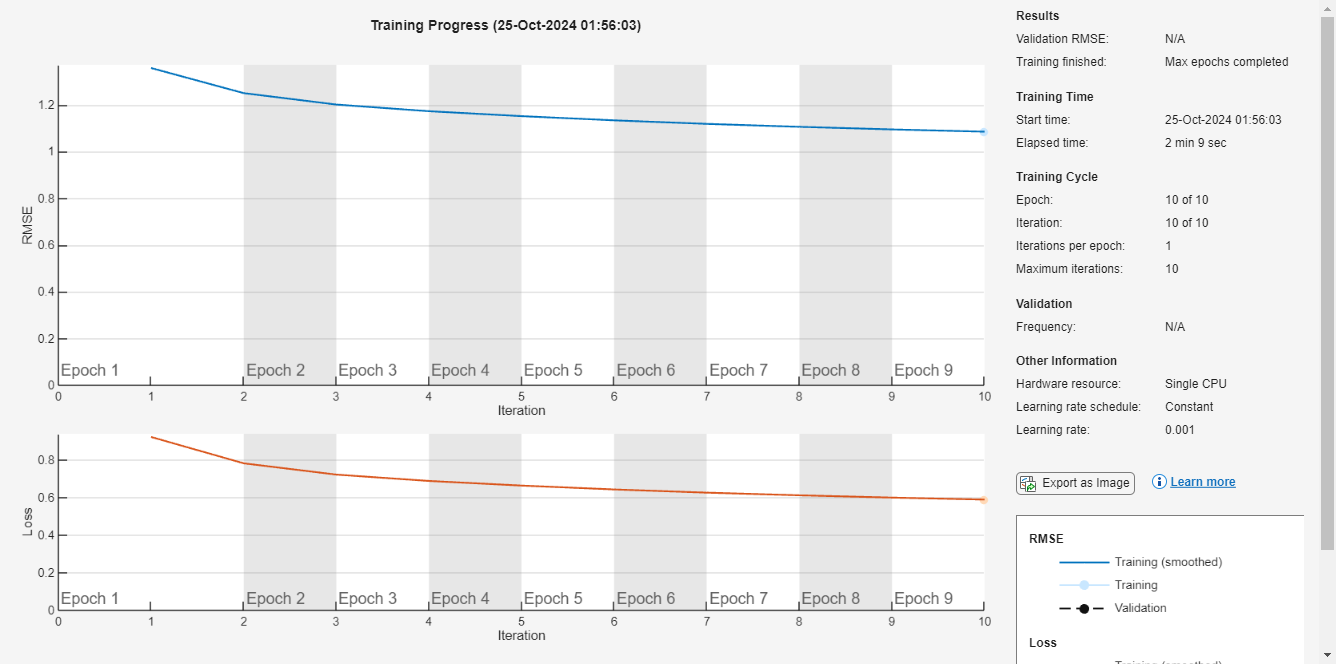


% Define LSTM network architecture
layers = [ ...
    sequenceInputLayer([130 10])  % 130 features
    flattenLayer
    lstmLayer(100, 'OutputMode', 'sequence')  % 100 hidden units
    fullyConnectedLayer(130)  % 130 responses
    regressionLayer];  % Regression layer for continuous output

% Training options
options = trainingOptions('adam', ... % adam (adaptive moment) is the optimizer (loss function which take the difference between the true input and the predicted input and outputs diff between them)
    'MaxEpochs', 10, ...  % Adjust as necessary
    'MiniBatchSize', 128, ...
    'GradientThreshold', 1, ...
    'Verbose', 0, ...
    'Plots', 'training-progress');

% Train the LSTM network with reshaped data
lstmNet = trainNetwork(reshapedInputs, reshapedOutputs, layers, options);

%seed sequence for generating music
seedSequence = reshapedInputs(:, :, 1);
disp('Seed Sequence: ');

Seed Sequence: 


disp(seedSequence);

         0    0.0000    0.0000    0.0016    0.0016    0.0016    0.0034    0.0034    0.0034    0.0041
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0 


generatedMusic = seedSequence;
numTimeSteps = 100;

for t = 1:numTimeSteps
    predictedNote = predict(lstmNet, generatedMusic);
    generatedMusic = [generatedMusic(:, 2:end), predictedNote];
end

disp('generated music sequence: ');

generated music sequence: 


disp(generatedMusic);

    0.0378    0.0378    0.0378    0.0378    0.0378    0.0378    0.0378    0.0378    0.0378    0.0378
    0.0097    0.0097    0.0097    0.0097    0.0097    0.0097    0.0097    0.0097    0.0097    0.0097
   -0.0078   -0.0078   -0.0078   -0.0078   -0.0078   -0.0078   -0.0078   -0.0078   -0.0078   -0.0078
    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014
   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012   -0.0012
   -0.0045   -0.0045   -0.0045   -0.0045   -0.0045   -0.0045   -0.0045   -0.0045   -0.0045   -0.0045
    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007
    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043    0.0043
   -0.0075   -0.0075   -0.0075   -0.0075   -0.0075   -0.0075   -0.0075   -0.0075   -0.0075   -0.0075
    0.0076    0.0076    0.0076    0.0076    0.0076    0.0076    0.0076    0.0076    0.0076 

function midiData = midiFromGeneratedSequence1(generatedMusic)
    % This function converts the generated music sequence to a MIDI matrix format
    % Input: generatedMusic - a matrix with rows corresponding to features (e.g., pitch, time, duration)
    % Output: midiData - MIDI matrix format for saving

    % Initialize the MIDI data matrix with the format [Time, Channel, Pitch, Velocity, Duration, Instrument, AdditionalColumn]
    numNotes = size(generatedMusic, 1);
    channel = 1;   % Example channel
    velocity = 64; % Example velocity
    instrument = 1; % Default instrument
    additionalColumn = 0; % Dummy column to avoid errors

    midiData = zeros(numNotes, 7); % Adjusted to have 7 columns
    midiData(:, 1) = generatedMusic(:, 1); % Time column
    midiData(:, 2) = channel;              % Channel column
    midiData(:, 3) = 1;                    % Pitch column (to be updated below)
    midiData(:, 4) = velocity;             % Velocity column
    midiData(:, 5) = generatedMusic(:, 3); % Duration column
    midiData(:, 6) = instrument;           % Instrument column
    midiData(:, 7) = additionalColumn;     % Dummy additional column

    % Extract pitch from the one-hot encoding
    for i = 1:numNotes
        % Find the index of the active pitch
        activePitch = find(generatedMusic(i, 2:end) == 1);
        if ~isempty(activePitch)
            midiData(i, 3) = activePitch - 1;  % Adjust for zero-based indexing
        else
            midiData(i, 3) = 0;  % Default to a MIDI pitch (e.g., 0 for silence)
        end
    end
end




midiData = midiFromGeneratedSequence1(generatedMusic);
% midiStruct = writemidi(midiData);

%save the MIDI structure to a file using writemidi
writemidi(midiData, 'GeneratedMusic.mid');

disp('Generated MIDI file saved successfully as GeneratedMusic.mid');

Generated MIDI file saved successfully as GeneratedMusic.mid
